Fs = 200; 
fp = 25;  fs = 50;  
% ========确定模拟滤波器指标======
Wp = 2*pi*fp /Fs   % ωpz

Wp =    0.785398163397448


Ws = 2*pi*fs/Fs   % ωsz

Ws =    1.570796326794897



% ======频率变换======
T = 2;
wp = 2/T*tan(Wp/2)

wp =    0.414213562373095


rp = 3;
ws = 2/T*tan(Ws/2)

ws =    1.000000000000000


rs =40;


% ======获得巴特沃兹低通滤波器阶数和3dB截止频率======

[N, wc] = buttord(wp, ws, rp, rs, 's')

N =      6


wc =    0.464162751561503


[B, A] = butter(N, wc, 's')   % 获得系统函数

B =                    0                   0                   0                   0                   0                   0   0.010000500037503


A =    1.000000000000000   1.793387157338609   1.608118748053530   0.914184872747480   0.346464456297936   0.083244432945405   0.010000500037503


% ======使用双线性变换法获得H(z)======
[Bz, Az] = bilinear(B, A ,1/T) 

Bz =    0.001737585527782   0.010425513166694   0.026063782916722   0.034751710555643   0.026063782916724   0.010425513166691   0.001737585527782


Az =    1.000000000000000  -2.659046466914583   3.446507115469452  -2.563396532484714   1.138899255022832  -0.281949931978517   0.030192034663570


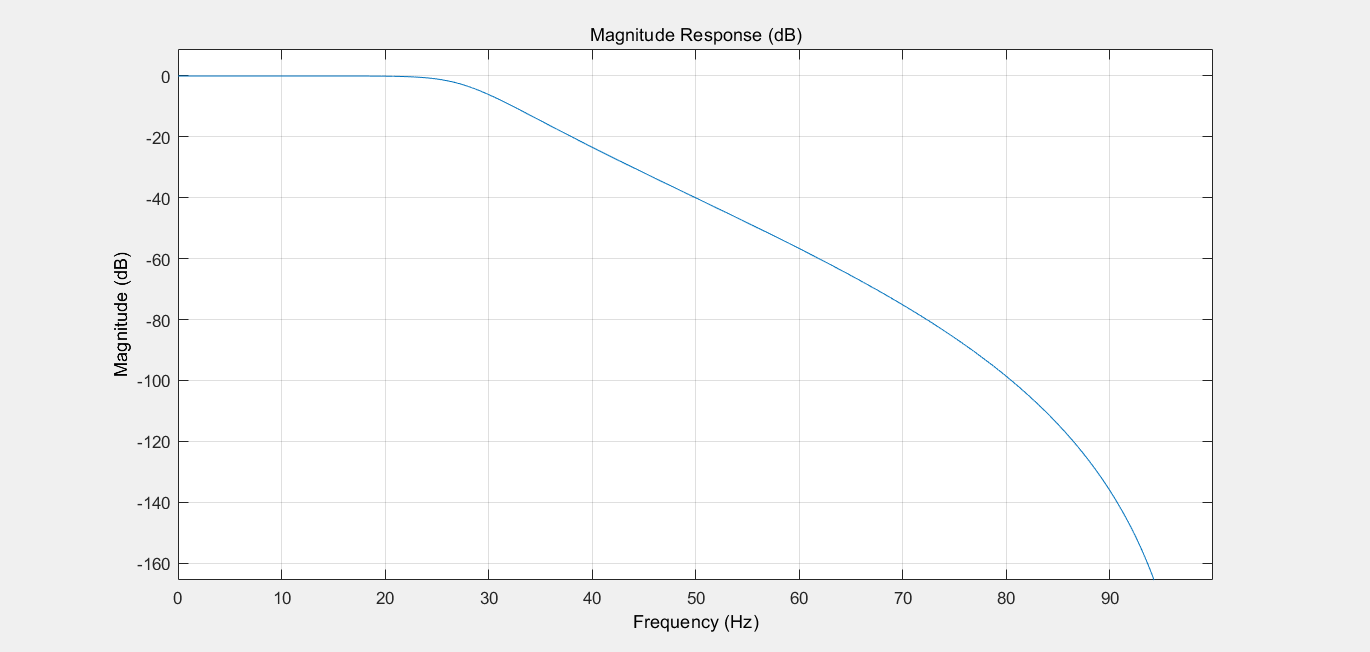


fvtool(Bz,Az,'Fs',Fs); % 显示滤波器图像

aaaa

Fs = 2000; 
fp = 25;  fs = 50;  
% ========确定模拟滤波器指标======
Wp = 2*pi*fp /Fs   % ωpz

Wp =    0.078539816339745


Ws = 2*pi*fs/Fs   % ωsz

Ws =    0.157079632679490



% ======频率变换======
T = 2;
wp = 2/T*tan(Wp/2)

wp =    0.039290107007670


rp = 3;
ws = 2/T*tan(Ws/2)

ws =    0.078701706824618


rs =40;


% ======获得巴特沃兹低通滤波器阶数和3dB截止频率======

[N, wc] = buttord(wp, ws, rp, rs, 's')

N =      7


wc =    0.040763640953422


[B, A] = butter(N, wc, 's')   % 获得系统函数

B = 	1.0e+-9 *

                   0                   0                   0                   0                   0                   0                   0   0.187029784583051


A =    1.000000000000000   0.183190139591204   0.016779313621722   0.000988388285568   0.000040290305195   0.000001136561903   0.000000020618968   0.000000000187030


% ======使用双线性变换法获得H(z)======
[Bz, Az] = bilinear(B, A ,1/T) 

Bz = 	1.0e+-8 *

   0.015572843015121   0.109010045434843   0.327029425761793   0.545050937716951   0.545048095546008   0.327030846847265   0.109009512527791   0.015572931832963


Az =    1.000000000000000  -6.633836751233490  18.869624707157204 -29.832836482183652  28.312450554241018 -16.128994888651889   5.106882183459931  -0.693289302855879


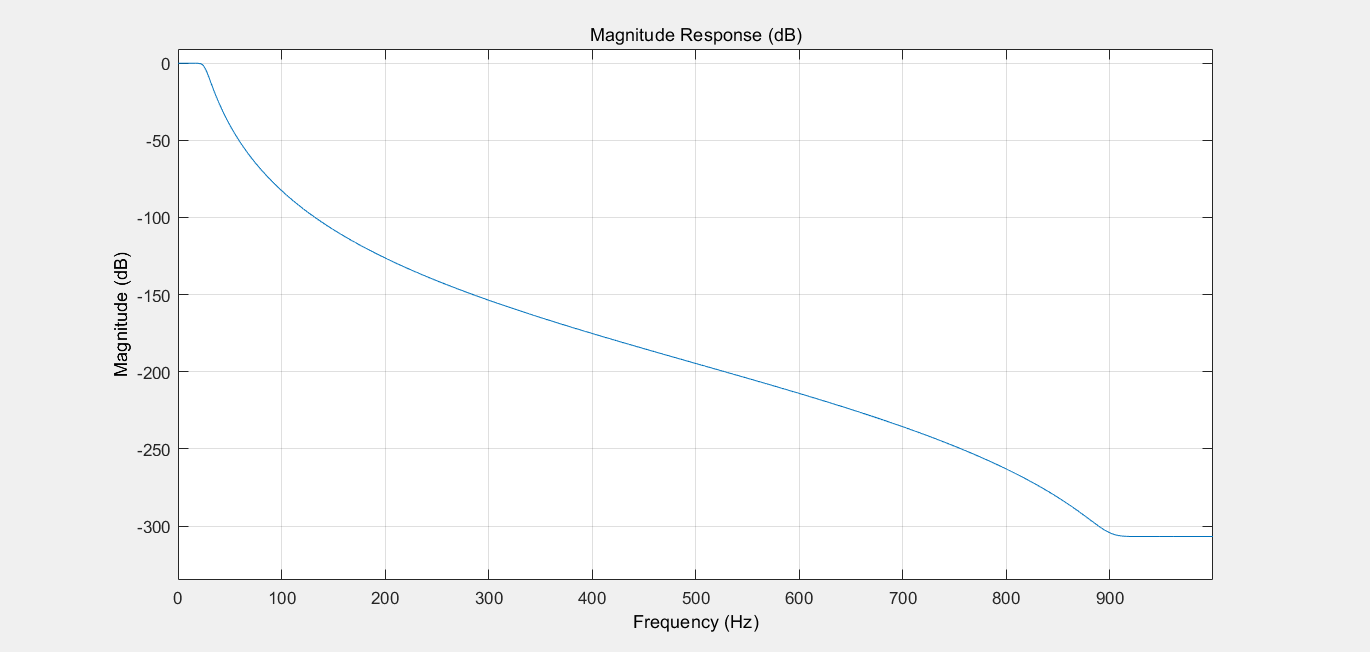


fvtool(Bz,Az,'Fs',Fs); % 显示滤波器图像


wpl = 0.2*pi; wsl = 0.1*pi; wpu = 0.4*pi; wsu=0.6*pi;
rs = 20;
rp = 2;
w = [wpl, wsl, wpu, wsu];
W = tan(w/2);
Wpl = W(1); Wsl = W(2); Wpu = W(3); Wsu= W(4);
Wpl*Wpu;
Wsl*Wsu;

% Wpl =W(2) *W(4)/W(3);
Wsl = W(1)*W(3)/W(4);
W0 = (Wpl+Wpu)/2; %中心频率
Bw = Wpu - Wpl;

[N, wc] = buttord([Wpl, Wpu], [Wsl, Wsu], rp, rs, 's')

N =      3


wc =    0.280727391382054   0.840915367530042



lambda_s = (W0^2 + Wsl^2)/(Wsl*Bw)

lambda_s =    4.439512162874652


ksp =  sqrt( ( 10^(rs/10) -1) / ( 10^(rp/10) -1  ) )

ksp =   13.010060434809038


N = log10(ksp)/log10(lambda_s)

N =    1.721332669117835



wp = 2*pi*[200, 400] ; ws = 2*pi*[100 , 600]

ws = 	1.0e+03 *

   0.628318530717959   3.769911184307752



[N, wc] = buttord(1, lambda_s, rp, rs, 's')

N =      2


wc =    1.407428857762305


[B, A] = butter(N, wc, 's')   % 获得系统函数

B =                    0                   0   1.980855989662107


A =    1.000000000000000   1.990404978722725   1.980855989662107


[Bz,Az] = bilinear(B,A,Fs);
